clear all;

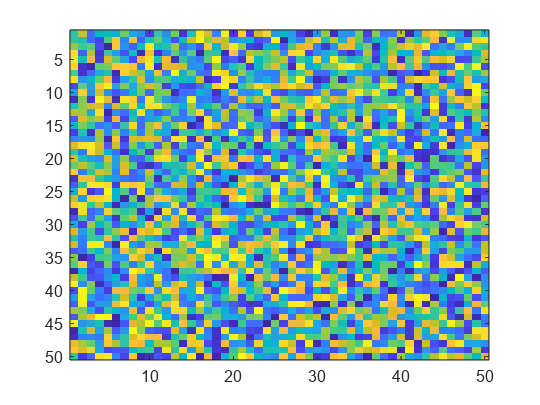

N = 50;
M = 50;

iter = 100;
A = randi(256,[M N])-1;

%A = zeros([M N]);
%A(10,10) = 1;

image(A)

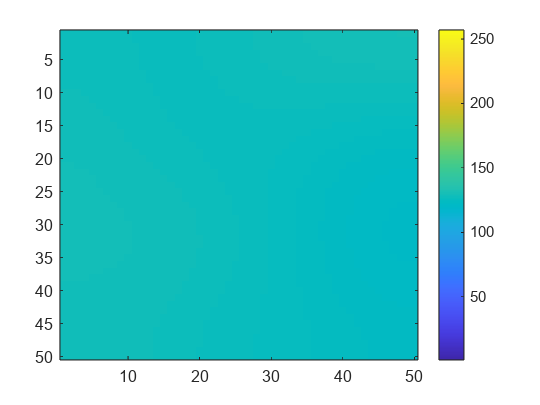


%colormap(mycmap)
B = A;
for i = 1:iter
    B = smear(B);
    image(B);
    colorbar;
    drawnow();
    pause(1/10);
end

mean(mean(A))

ans = 125.3975

mean(mean(B))

ans = 124.9915

function [B] = smear(A)
    [M N] = size(A);
    B = A;
    for i = 1:M
        for j = 1:N
            i_start = i - 1;
            i_end = i + 1;
            j_start = j - 1;
            j_end =  j + 1;
            switch i
                case 1
                    i_start = 1;
                case M
                    i_end = M;
            end
            switch j
                case 1
                    j_start = 1;
                case N
                    j_end = N;
            end
            B(i,j) = mean(mean(B(i_start:i_end,j_start:j_end)));
        end
    end
end